生成一个随机的训练集

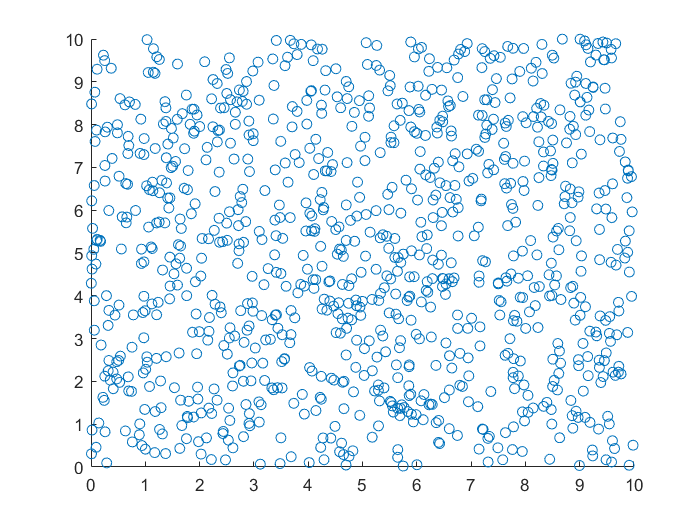

clc;clear;clf;
train_set = 10*rand(1000,2);
x0 = train_set(:,1);
y0 = train_set(:,2);
scatter(x0,y0)

首先绘制一下迭代等高线图

n = 100;
k = linspace(0.01,0.03,n);
b = linspace(5,7,n);
[kk,bb]=meshgrid(k,b);
z = 0;
for i = 1:length(x0)
    z = z + ( kk.*x0(i)+bb-y0(i)*ones(n,n) ).^2;
end
z = z/2/length(x0);
min(min(z))

ans = 3.9794

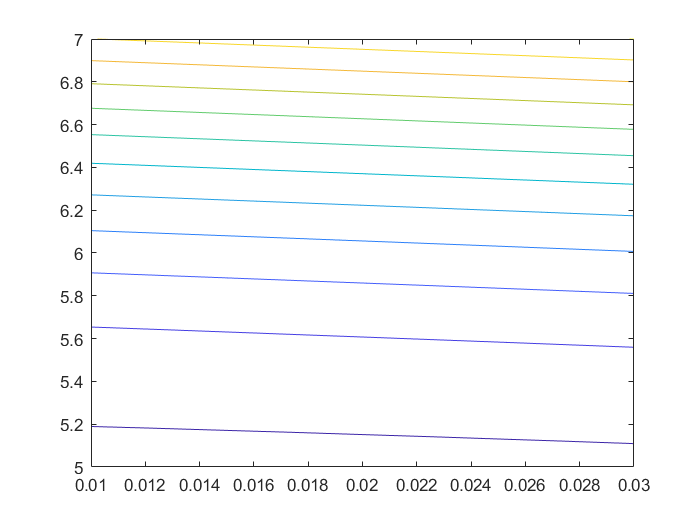

contour(kk,bb,z);

然后我们试验一下梯度下降方法

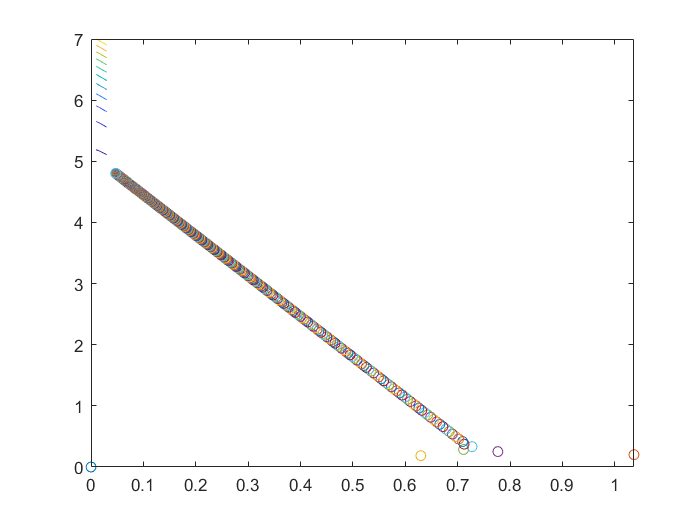

%给出初始值
k = 0;
b = 0;
a = 0.04;%换称0.1就发散了，乐
figure
contour(kk,bb,z)
hold on
for i = 1:1000
    k1 = 0;
    k2 = 0;
    for j = 1:length(x0)
        k1 = k1 + ( k*x0(j) + b - y0(j) ) * x0(j);
    end
    for j = 1:length(x0)
        k2 = k2 + ( k*x0(j) + b - y0(j) );
    end
    plot(k,b,'o')
    k = k - a * k1 / length(x0);
    b = b - a * k2 / length(x0);
end

看看是否收敛

hold off

k = 0;
b = 0;
a = 0.04;%换称0.1就发散了，乐
n = 100000;
x00 = linspace(0,10,100);
kk = zeros(1,n);
bb = zeros(1,n);
for i = 1:n
    k1 = 0;
    k2 = 0;
    for j = 1:length(x0)
        k1 = k1 + ( k*x0(j) + b - y0(j) ) * x0(j);
    end
    for j = 1:length(x0)
        k2 = k2 + ( k*x0(j) + b - y0(j) );
    end
    k = k - a * k1 / length(x0);
    b = b - a * k2 / length(x0);
    kk(i) = k;
    bb(i) = b;
end
xx = 1:n;
z = 0;
for i = 1:length(x0)
    z = z + ( kk(n)*x0(i)+bb(n)-y0(i) )^2;
end
z = z/2/length(x0)

z = 3.9747

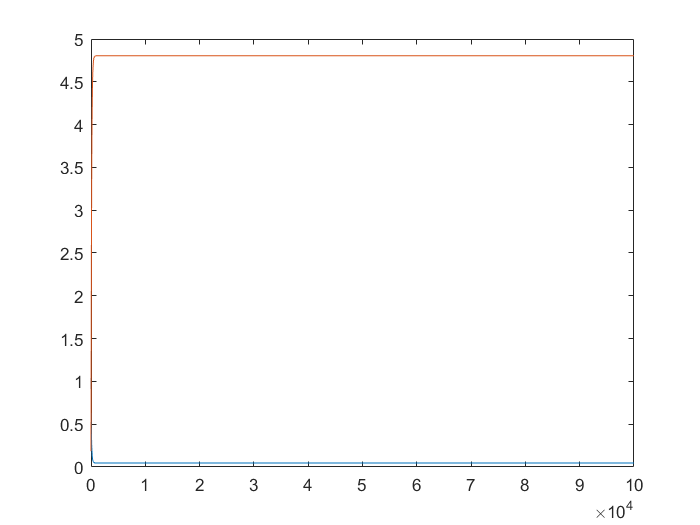

plot(xx,kk,xx,bb)

%到后面就收敛了，不过迭代次数有点儿多